% Upload Data
folder = fullfile('C:', 'Users', 'ariay', 'Desktop', 'Desktop', 'PHY293', '2-weight', 'PHY293 2-Weight', 'trials');

fileNames = {
    'trial8bottomleft.txt', 'trial8bottomright.txt', 'trial8left.txt', ...
    'trial9bottom.txt', 'trial9left.txt', ...
    'trial9secondtoright.txt', 'trial9topright.txt', 'trial10bottom.txt', ...
    'trial12mostright.txt', 'trial12top.txt'};

ptm = 0.1155; % microns per pixel
dt = 0.5; % time interval [s]

% Initialize cell arrays to store cumulative squared distances & slopes
cumulative_distances = cell(1, length(fileNames)); 
slopes = zeros(1, length(fileNames)); % Array to store slope for each trial
all_step_distances = [];

% Loop over each file and calculate squared distance traveled as a function of time
figure;
for k = 1:length(fileNames)
    % Load data
    filename = fullfile(folder, fileNames{k});
    opts = detectImportOptions(filename, 'NumHeaderLines', 2); 
    data = readtable(filename, opts);
    x = data{:, 1} * ptm; % unit conversion
    y = data{:, 2} * ptm; 

    % Calculate r^2 & r for each step
    dx = diff(x);
    dy = diff(y);
    r_squared = dx.^2 + dy.^2;
    r = sqrt(r_squared); 

    % Define time vector based on length of r_squared
    time_vector = (1:length(r_squared)) * dt; 
    
    % Cumulative squared distance for MSD
    cumulative_distances{k} = cumsum(r_squared);
    all_step_distances = [all_step_distances, r'];  % Concatenate step distances for histogram (r' = transpose r, column to row vector)

    % Fit a linear model to the MSD for this trial
    p = polyfit(time_vector, cumulative_distances{k}, 1); % Linear fit
    slopes(k) = p(1); % Store the slope (p(1)) for this trial
    
    %Plot MSD for each file
    % plot(time_vector, cumulative_distances{k}, '-o', 'DisplayName', sprintf('Trial %d', k));

    % % Plot cumulative squared distance traveled for each file
    % plot(time_vector, cumulative_distances{k}, '-o', 'DisplayName', sprintf('Trial %d', k));
    % hold on;
    % fprintf('Trial:%d, m = %.4f\n', k, slopes(k));
    % % 
    %%% Linear Regression
    xlin = time_vector';
    ylin = (cumulative_distances{k}) .* 10e-12;
    dy = repmat(0.005e-12, 1, length(time_vector))';

    % Number of measurements
    N = length(xlin);

    % Calculate sums needed for the formulas
    Sx = sum(xlin);
    Sy = sum(ylin);
    Sxy = sum(xlin .* ylin);
    Sxx = sum(xlin .* xlin);
    Syy = sum(ylin .* ylin);

    % Calculate the determinant delta (∆)
    delta = N * Sxx - Sx^2;

    % Calculate slope (m) and intercept (b)
    m = (N * Sxy - Sx * Sy) / delta;
    b = (Sxx * Sy - Sx * Sxy) / delta;

    % Calculate the variance of y(x)
    y_fit = m * xlin + b;
    variance = sum((ylin - y_fit).^2) / (N - 2);

    % Calculate the standard deviation of the slope (sm) and intercept (sb)
    sm = sqrt(N * variance / delta);
    sb = sqrt(Sxx * variance / delta);

    % Calculate R² (coefficient of determination)
    y_mean = mean(ylin);
    SStot = sum((ylin - y_mean).^2);  % Total sum of squares
    SSres = sum((ylin - y_fit).^2);    % Sum of squares of residuals
    R_squared = 1 - (SSres / SStot);

    % Reduced Chi-Squared Calculation
    chi_squared = sum(((ylin - y_fit).^2) ./ dy.^2);  % Chi-squared calculation
    reduced_chi_squared = chi_squared / (N - 2);   % Reduced chi-squared (N-2 degrees of freedom)

    % Display results
    disp(['Trial = ', num2str(k)]);
    disp(['Slope (m) = ', num2str(m), ' ± ', num2str(sm)]);
    disp(['Intercept (b) = ', num2str(b), ' ± ', num2str(sb)]);
    disp(['R² = ', num2str(R_squared)]);
    disp(['Chi-Squared = ', num2str(chi_squared)]);
    disp(['Reduced Chi-Squared = ', num2str(reduced_chi_squared)]);

    % % Plot the data and the fit
    % figure;
    % errorbar(xlin, ylin, dy, 'o', 'MarkerSize', 4, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r', 'LineStyle', 'none'); % Scatter plot with error bars
    % hold on;
    % plot(xlin, y_fit);  % Plot the fit line
    % xlabel('time ()');
    % ylabel('y');
    % title(sprintf('Linear Regression with Errors, Trial %d', k));
    % grid on;
    % legend('Data', 'Fit');
    % hold off;

    % Calculations
    % Part 1, Method 1: Eistein w fitted Drag Coefficient
    % Avg Drag Coefficient
    D_Einstein = mean(slopes) / 4 * 1e-12 %[m^2/s]D = slope / 4 for 2D diffusion
    % k
    T = 296.5; %+/-0.1 Kelvin
    r = 0.95 * 1e-6; %+/10^-7 meters (diamter/2, 1.95/2)
    eta = 0.961 * 0.001; %Pa*s adjusted eta based off of 298K
    gamma = 6 * pi * eta * r; %γ = 6πηr, η=8.9e-4, r=v1e-6
    k_Einstein = D_Einstein * gamma / T
    % N_A
    N_A_Einstein = 8.314/k_Einstein
    
    % Error for D, k, and N_A
end

Trial = 1


Slope (m) = 6.0732e-12 ± 5.3874e-14


Intercept (b) = -1.1931e-11 ± 1.8623e-12


R² = 0.99088


Chi-Squared = 476835745.7738


Reduced Chi-Squared = 4075519.1946


D_Einstein = 1.5183e-14

k_Einstein = 8.8122e-25

N_A_Einstein = 9.4347e+24

Trial = 2


Slope (m) = 5.3572e-12 ± 3.2978e-14


Intercept (b) = 5.9619e-12 ± 1.14e-12


R² = 0.99559


Chi-Squared = 178670728.9595


Reduced Chi-Squared = 1527100.2475


D_Einstein = 2.8576e-14

k_Einstein = 1.6585e-24

N_A_Einstein = 5.0128e+24

Trial = 3


Slope (m) = 6.3802e-12 ± 2.9712e-14


Intercept (b) = -1.1238e-11 ± 1.0271e-12


R² = 0.99747


Chi-Squared = 145036046.1176


Reduced Chi-Squared = 1239624.3258


D_Einstein = 4.4527e-14

k_Einstein = 2.5843e-24

N_A_Einstein = 3.2171e+24

Trial = 4


Slope (m) = 6.7947e-12 ± 9.0345e-14


Intercept (b) = -2.995e-11 ± 3.1231e-12


R² = 0.97973


Chi-Squared = 1340982919.697


Reduced Chi-Squared = 11461392.476


D_Einstein = 6.1513e-14

k_Einstein = 3.5702e-24

N_A_Einstein = 2.3287e+24

Trial = 5


Slope (m) = 6.0719e-12 ± 4.1883e-14


Intercept (b) = 1.6829e-11 ± 1.4479e-12


R² = 0.99446


Chi-Squared = 288200559.4703


Reduced Chi-Squared = 2463252.645


D_Einstein = 7.6693e-14

k_Einstein = 4.4512e-24

N_A_Einstein = 1.8678e+24

Trial = 6


Slope (m) = 6.9054e-12 ± 6.5226e-14


Intercept (b) = 2.6555e-12 ± 2.2548e-12


R² = 0.98967


Chi-Squared = 698966523.7381


Reduced Chi-Squared = 5974072.8525


D_Einstein = 9.3956e-14

k_Einstein = 5.4532e-24

N_A_Einstein = 1.5246e+24

Trial = 7


Slope (m) = 7.216e-12 ± 6.0552e-14


Intercept (b) = -1.5685e-11 ± 2.0932e-12


R² = 0.99183


Chi-Squared = 602380808.0257


Reduced Chi-Squared = 5148553.9147


D_Einstein = 1.1200e-13

k_Einstein = 6.5002e-24

N_A_Einstein = 1.2790e+24

Trial = 8


Slope (m) = 5.3937e-12 ± 9.9128e-14


Intercept (b) = -2.2376e-11 ± 3.4267e-12


R² = 0.96198


Chi-Squared = 1614373635.9085


Reduced Chi-Squared = 13798065.2642


D_Einstein = 1.2548e-13

k_Einstein = 7.2828e-24

N_A_Einstein = 1.1416e+24

Trial = 9


Slope (m) = 6.2738e-12 ± 3.1134e-14


Intercept (b) = 4.4553e-12 ± 1.0763e-12


R² = 0.99713


Chi-Squared = 159249449.7054


Reduced Chi-Squared = 1361106.4077


D_Einstein = 1.4117e-13

k_Einstein = 8.1932e-24

N_A_Einstein = 1.0147e+24

Trial = 10


Slope (m) = 6.6264e-12 ± 5.4242e-14


Intercept (b) = -1.5138e-11 ± 1.8751e-12


R² = 0.99222


Chi-Squared = 483385689.851


Reduced Chi-Squared = 4131501.6227


D_Einstein = 1.5773e-13

k_Einstein = 9.1546e-24

N_A_Einstein = 9.0817e+23

Plotting the Data and Fit

% plot(time_vector, polyval(p, time_vector), '--r', 'DisplayName', 'Avg Fit', 'LineWidth', 3);
% xlabel('Time (s)');
% ylabel('Mean Squared Displacement (\mum^2)');
% title('MSD vs Time for Each Trial');
% legend show;
% hold off;

Calculations

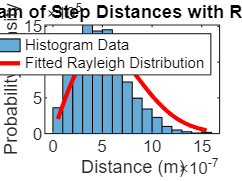

% Part 2: Method 2: Rayleigh w Fitted Histogram
[h_counts, edges] = histcounts(all_step_distances * 1e-6, 'Normalization', 'pdf', 'BinMethod', 'auto');
bin_centers = edges(1:end-1) + diff(edges)/2;

% Fit function to histogram data
fit_func = fittype('r/(2*D*t) * exp(-r^2/(4*D*t))', 'independent', 'r', 'coefficients', {'D', 't'});
initial_D = 2.4509e-13; % Initial guess for D
initial_t = dt;      % Initial guess for t
[fit_result, gof] = fit(bin_centers(:), h_counts(:), fit_func, 'StartPoint', [initial_D, initial_t]);

D_Histogram = fit_result.D;
k_Histogram = D_Histogram * gamma / T;
N_A_Histogram = 8.314 / k_Histogram;

% Plot the histogram with the fitted Rayleigh distribution
figure;
histogram(all_step_distances * 1e-6, 'Normalization', 'pdf', 'BinMethod', 'auto');
hold on;

% Overlay fitted Rayleigh distribution
r_values = linspace(min(bin_centers), max(bin_centers), 100); % Range of r values for fit
fitted_curve = feval(fit_result, r_values); % Evaluate the fitted Rayleigh function at r_values
plot(r_values, fitted_curve, 'r-', 'LineWidth', 2); % Plot the fitted curve

xlabel('Distance (m)');
ylabel('Probability Density');
title('Histogram of Step Distances with Rayleigh Fit');
legend('Histogram Data', 'Fitted Rayleigh Distribution');
hold off;


% Part 2: Method 2: Max Likelihood w Fitted Histogram
% Define the log-likelihood function for D
log_likelihood = @(D) -sum(log(all_step_distances * 1e-6 / (2 * D * dt)) - (all_step_distances * 1e-6).^2 / (4 * D * dt));

% Initial guess for D
initial_D = 2.4509e-13;

% Calculations
D_MLE = fminsearch(log_likelihood, initial_D)

D_MLE = 1.5538e-13

k_MLE = D_MLE * gamma / T

k_MLE = 9.0184e-24

N_A_MLE = 8.314 / k_MLE

N_A_MLE = 9.2190e+23